1. Use the **roots** function to find the roots of the polynomial.

p = [1, 0, -10, 0, 21, 0];
r = roots(p);
disp(r);

         0
   -2.6458
   -1.7321
    2.6458
    1.7321



2. Create an anonymous function for p(x) and substitute the roots you found in question 1 into it to verify your answer.

f = @(x) x.^5 - 10*x.^3 + 21*x;
y = f(r);
disp(y);

   1.0e-12 *

         0
   -0.1705
   -0.0568
   -0.0995
    0.0142



fplot(f,[-3 3]);
hold on;
lr = cell(1, numel(r));
for i = 1:length(r)
    lr{i} = r(i);
end
disp(lr);

    {[0]}    {[-2.6458]}    {[-1.7321]}    {[2.6458]}    {[1.7321]}



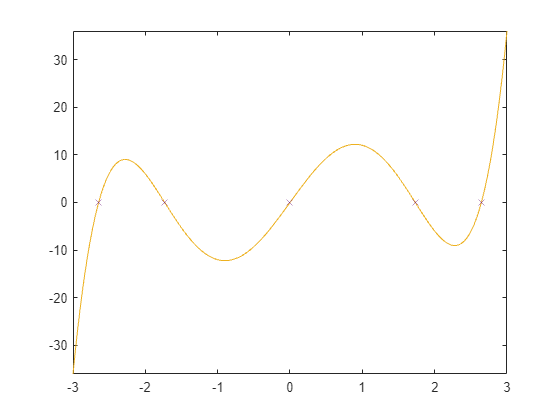

plot(cell2mat(lr), f(r), 'x');
hold off;

3. Use the **roots** function to find the roots of the polynomial (no template). Display only the real roots.

q = @(x) -2*x.^6 - 1.5*x.^4 + 10*x + 2;
coef = [-2, 0, -1.5, 0, 0, 10, 2];
polynomial_roots = roots(coef);
disp(polynomial_roots);

   1.3213 + 0.0000i
   0.4201 + 1.4191i
   0.4201 - 1.4191i
  -0.9809 + 0.8761i
  -0.9809 - 0.8761i
  -0.1997 + 0.0000i



realRoots = polynomial_roots(imag(polynomial_roots)==0);
disp(realRoots);

    1.3213
   -0.1997



disp(realRoots(1));

    1.3213



sub = q(realRoots);
disp(sub);

   1.0e-13 *

   -0.1421
   -0.0044



4. Use the **fzero** function to locate all roots of  

on the interval [0,5]. Plot the function with a grid and mark the roots with large green diamonds. For this question make a function file to hold the function. You will have to divide the interval into pieces using an appropriate step size, h. First try 

h = 2, then plot the function and roots to see if it found them all. If not, adjust your value of h and try again.

number of brackets:
     1



     2     4



ans = "interval in loop: 2"

ans = "roots: 2"

ans = "interval in loop: 4"

ans = "roots: 4"

number of brackets:
     1



     2     3



ans = "interval in loop: 2"

ans = "roots: 2"

ans = "interval in loop: 3"

ans = "roots: 3"

number of brackets:
     1



    2.0000    2.5000



ans = "interval in loop: 2"

ans = "roots: 2"

ans = "interval in loop: 2.500000e+00"

ans = "roots: 2.500000e+00"

number of brackets:
     3



    2.0000    2.1000
    4.5000    4.6000
    4.8000    4.9000



ans = "interval in loop: 2"

ans = "roots: 2"

ans = "interval in loop: 4.500000e+00"

ans = "roots: 4.500000e+00"

ans = "interval in loop: 4.800000e+00"

ans = "roots: 4.800000e+00"

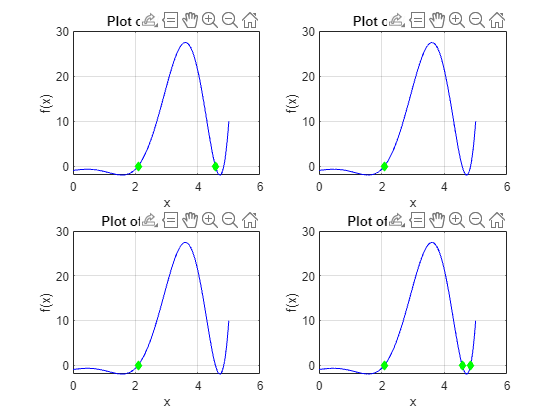

f = @(x) exp(x).*cos(x).^2-2;
% fplot(f, [0,5]);
x = linspace(0,5,1000);
choose_h = [2, 1, 0.5, 0.1];
rootsAll = cell(1, numel(choose_h));
for i = 1:length(choose_h)
    h = choose_h(i);
    subplot(2, 2, i);
    plot(x, f(x), 'b-');
    xlabel('x');
    ylabel('f(x)');
    title(['Plot of f(x) for h = ', num2str(h)]);
    grid on;
    hold on;

    a = incsearch_stepsize(f, 0, 5, choose_h(i));
    disp(a);
    roots_array = [];
    for j = 1:length(a)
        sprintf("interval in loop: %d", a(j))
        roots = fzero(f, a(j));
        sprintf("roots: %d", a(j))
        roots_array = [roots_array, roots];
    end
    rootsAll{i} = roots_array;
    % disp(rootsAll{i});
    plot(rootsAll{i}, f(rootsAll{i}), 'gd', 'MarkerSize', 5, 'MarkerFaceColor','g');

    hold off
end

% ?????????????????????????????????????????????????????????????????????????????

5. Write a script that solves                                     

using Fixed Point Iteration. Choose your own stopping criteria and keep track of the error at each iteration. Keep in mind that you can choose any of the following 4 formulas for your fixed point iteration:                                   

Test all of them to see which work and which don’t.

h = @(x) x.^2 - x - exp(-x);
h_prime = @(x) 2*x - 1 + exp(-x)

h_prime = function_handle with value:
    @(x)2*x-1+exp(-x)


g1 = @(x) -exp(-x) + x.^2;
dg1 = @(x) 2*x + exp(-x)

dg1 = function_handle with value:
    @(x)2*x+exp(-x)


fixedPoint(g1, dg1, 100, 0.0001);

error slope more than 1


g2 = @(x) sqrt(exp(-x) + x);
dg2 = @(x) -(exp(-x) - 1)/(2*(x + exp(-x))^(1/2))

dg2 = function_handle with value:
    @(x)-(exp(-x)-1)/(2*(x+exp(-x))^(1/2))


fixedPoint(g2, dg2, 100, 0.0001);

Number of iterations: 7
x = 1      1.1696      1.2166        1.23      1.2338      1.2349      1.2352


g3 = @(x) -log(x.^2 - x);
dg3 = @(x) (2*x - 1)/(- x^2 + x)

dg3 = function_handle with value:
    @(x)(2*x-1)/(-x^2+x)


fixedPoint(g3, dg3, 1000, 0.01);

error slope more than 1


g4 = @(x) 1 + exp(-x)./x;
dg4 = @(x) - exp(-x)/x - exp(-x)/x^2;
fixedPoint(g4, dg4, 100, 0.0001);

Number of iterations: 11
x = 1      1.3679      1.1862      1.2575      1.2261      1.2393      1.2337      1.2361       1.235      1.2355      1.2353


6. Write a function that takes an initial guess as input then locates a root of  

using the Newton-Raphson Method. Remember you will have to differentiate the function to get the formula. Choose your own convergence criterion.

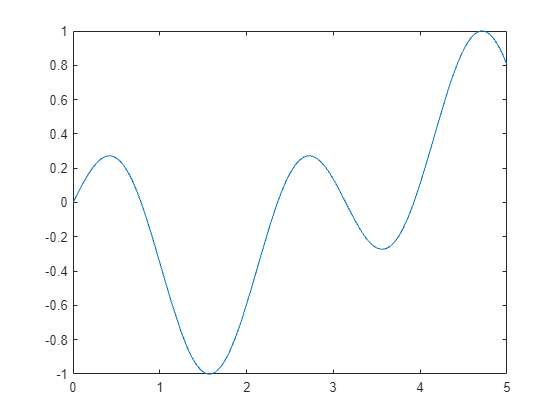

clf reset;
h = @(x) sin(x)*cos(2*x);
dif_h=@(x) cos(2*x)*cos(x) - 2*sin(2*x)*sin(x);
fplot(h, [0, 5]);

[root, n] = newt(h, dif_h, 1, 0.0001);
disp(root);

    0.7854



disp(n);

     4



7. Use your function from question 7 to find all roots of r(x) on the interval [–π,π].

interval = [-pi:0.1:pi];
tol = 0.0001;
rootsList = zeros(1, length(interval));
for i = 1:length(interval)
    rootsList(i) = newt(h, dif_h, interval(i), tol);
end
disp(rootsList);

   -3.1416   -3.1416   -3.1416   -3.1416   -6.2832   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -3.1416   -3.9270    5.4978   -0.0000   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854  -12.5664    0.7854   -0.0000    0.0000         0         0   -0.0000    0.0000   -0.7854    2.3562    0.7854    0.7854    0.7854    0.7854    0.7854    0.7854    0.7854    0.7854    2.3562         0  -14.9226    3.9270    3.9270    2.3562    2.3562    2.3562    2.3562    2.3562    2.3562    2.3562    2.3562    3.9270    3.1416    3.1416    3.1416    3.1416



fplot(h, [-pi, pi]);

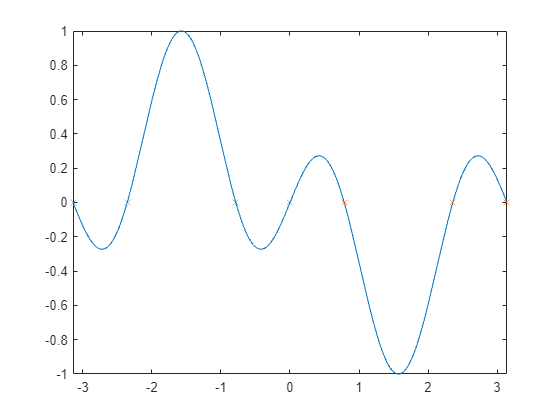

hold on;
plot(rootsList, arrayfun(h, rootsList), 'x');
xlim([-pi, pi]);
hold off;

8. Write a script that locates all roots of  

using the Bisection Method. Locate brackets by using the incremental search method you wrote before.

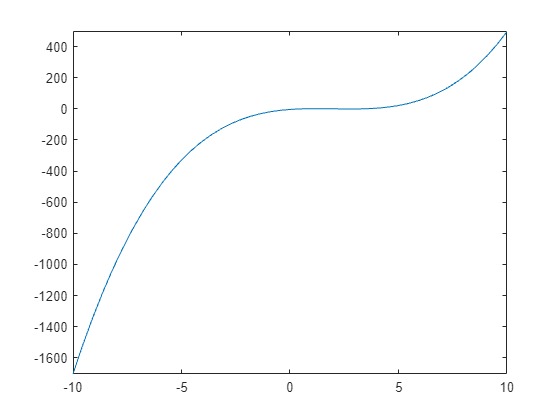

clf reset;
w = @(x) x.^3 - 6*x.^2 +10*x -4;
fplot(w, [-10, 10]);

bracket = incsearch_stepsize(w, -10, 10, 0.3)

number of brackets:
     3



bracket =     0.5000    0.8000
    1.7000    2.0000
    3.2000    3.5000


for i=1:length(bracket)

roots = 0.5858

    roots = bisect(w, bracket(1), bracket(2), 0.0001);

roots = 2

roots = 2

roots = 3.4143

end

9. The volume of liquid V in a hollow horizontal cylinder of radius r and length L is related to the depth of the liquid h by,

Determine *h* given *r* = 2m, *L* = 5m, and *V* = 8m.

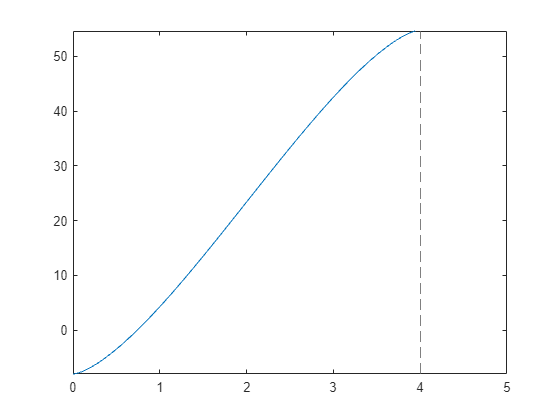

v_func = @(h) (4*acos((2-h)./2)-(2-h).*sqrt(2*2*h-h.^2)).*5-8;
fplot(v_func, [0, 5]);

ansW = fzero(v_func, 1)

ans = 0.7400

v_func(ansW)

ans = 1.5532e-04

10. Determine the location of the horizontal tangents (turning points) of

on the interval [–π,π]. Plot the figure and mark the turning points with thick, large red circles with blue faces 

% Step 1: Create a range of x-values
x = linspace(-pi, pi, 1000);

% Define the function m(x)
m = @(x) cos(x.^2/2) + cos(2*x);
dm = derivative(m, x)

dm = function_handle with value:
    @(f,x)(f(x+1e-6)-f(x))/1e-6


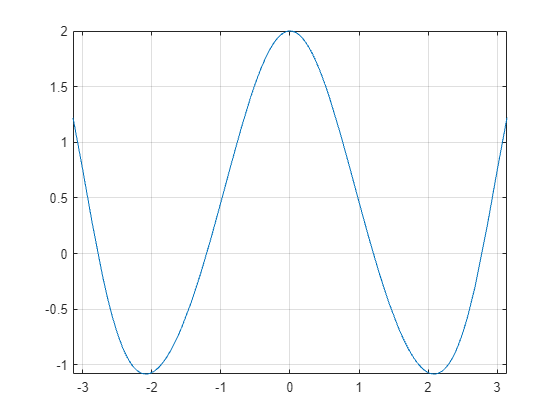

fplot(m, [-pi, pi]);
grid on

% ?????????????????????????????????????????????????????????????????????????????